# Differential Equation Solver

## Basic Form of Differential Equation Solver

clc;
syms y(t) t

Dy = diff(y, t);
D2y = diff(y, t, 2);

eqn = D2y + 4*Dy + 3*y == 0;
ySol = dsolve(eqn);

## Differential Equation Solver with One Initial Condition

clear
syms y(t) t

Dy = diff(y, t);
D2y = diff(y, t, 2);

eqn = Dy/3 == power(t, 2)*y;
cond = y(0) == 1;

ySol(t) = dsolve(eqn, cond);

## Differential Equation Solver with Multi Initial Conditions

clear
syms y(t) t

Dy = diff(y, t);
D2y = diff(y, t, 2);

m = 1;
b = 3;
k = 10;
eqn = m*D2y + b*Dy + k*y == sin(t);

cond1 = y(0) == 1;
cond2 = Dy(0) == 0;
cond = [cond1, cond2];

ySol(t) = dsolve(eqn, cond);

%ezplot(ySol, [0, 5]);
%fplot(ySol, [0, 5]);

## Differential Equation Solver with Laplace Transform

clear
syms t s Y

m = 1;
b = 3;
k = 10;
%eqn = m*D2y + b*Dy + k*y == sin(t)

cond0 = 1;
cond1 = 0;

f = sin(t);
F = laplace(f, t, s);

Y1 = s*Y - cond0;
Y2 = s*Y1 - cond1;

Sol = solve(m*Y2 + b*Y1 + k*Y - F, Y);
ySol = ilaplace(Sol, s, t);

%ezplot(ySol, [0, 5]);
%fplot(ySol, [0, 5]);

## Decorating the Function Plotting

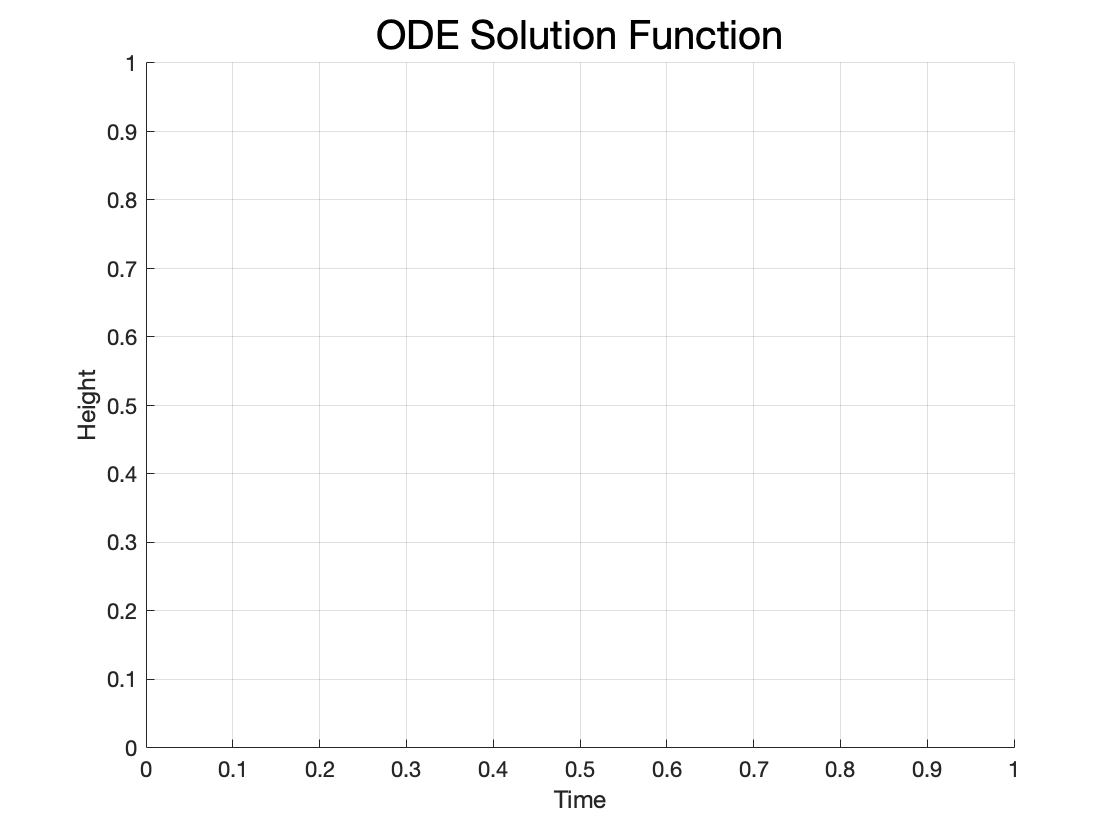

%fplot(ySol, [0, 5], "LineStyle", "--", "Color", "black", "LineWidth",3)
grid on
title("ODE Solution Function", "FontSize", 20)
xlabel("Time")
ylabel("Height")

## Other Useful Functions

a = 3;
H = heaviside(t - a);
t = 0:0.01:5;
%plot(t, H)
%hold on

delta = dirac(t - a);
%plot(t, delta)
%hold on

ramp = (t-a).*H;
%plot(t, ramp)
%grid on